# Discretización

## Ventanas

Diseñar 2 ventanas de N = 1024 muestras con las funciones dedicadas. Plotearlas en tiempo y en frecuencia.

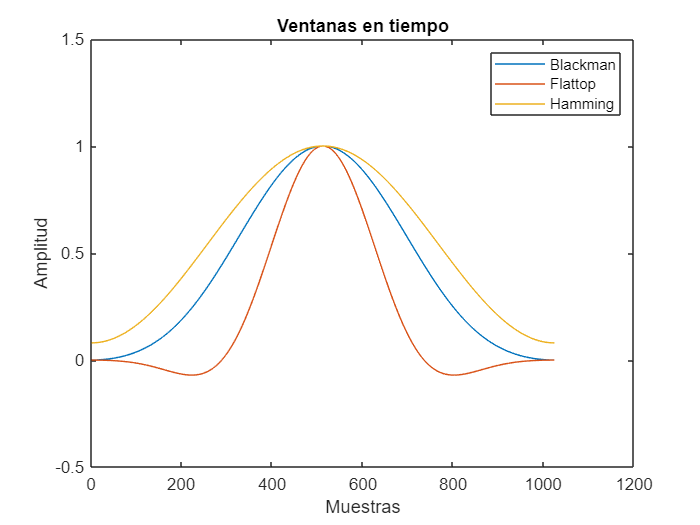

N = 1024;
w_hamming = hamming(N);
w_flattop = flattopwin(N);
w_rect = rectwin(N);
w_blackman = blackman(N);

% Creamos una tabla donde tengan los puntos de cada una de las ventanas
% anteriores:
windows = table(w_blackman, w_flattop, w_hamming, 'VariableNames',["Blackman" "Flattop" "Hamming"]);

% Plotear en tiempo la forma de estas ventanas
figure
plot(windows{:,:})

% con el siguiente argumento podemos poner los títulos de las columnas de
% forma automática
legend(windows.Properties.VariableNames)

ylim([-0.5 1.5])
xlabel("Muestras")
ylabel("Amplitud")
title("Ventanas en tiempo")

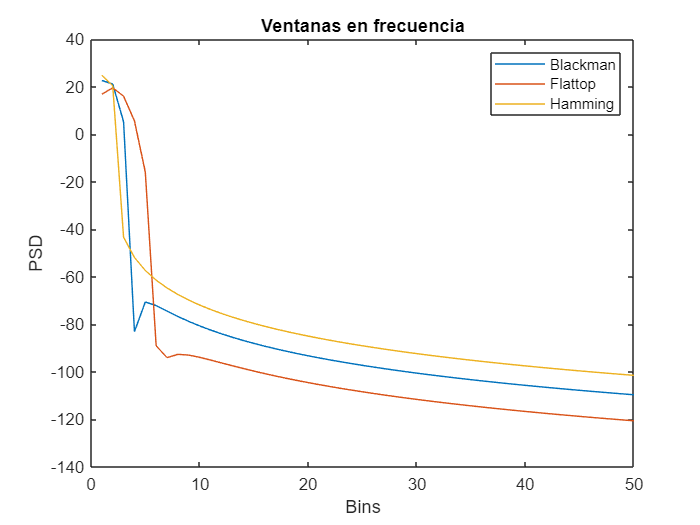

% Mostramos la representación espectral de cada una de las ventanas:
[Pxx,w] = periodogram(windows{:,:},[],N,[]);
windows_spectral = array2table(Pxx,"VariableNames",windows.Properties.VariableNames);

figure

%pow2db() convierte a escala logarítmica
plot(pow2db(windows_spectral{:,:}))
legend(windows.Properties.VariableNames)
xlabel("Bins")
ylabel("PSD")
title("Ventanas en frecuencia")
xlim([0 50])

**Ejemplo**: Generar las siguientes formas de onda con 1024 muestras y guardar cada una en un campo de una tabla

- 
$$x\left(t\right)=\cos \left(4t\right)$$


- 
$$x\left(t\right)=\cos \left(4t\right)+\cos \left(4\ldotp 5t\right)$$


- 
$$x\left(t\right)=\cos \left(4t\right)+\cos \;\left(8t\right)$$


- 
$$x\left(t\right)=\cos \left(4t\right)+0\ldotp 001\cos \left(8t\right)$$


Plotear temporalmente y en el espacio de frecuencias:

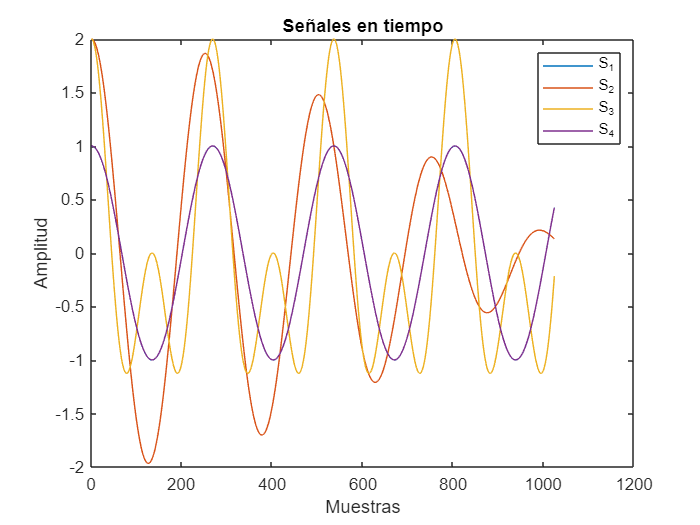

%Function handles de las ecuaciones previas

x_1 = @(t) cos(4.*t);
x_2 = @(t) cos(4.*t) + cos(4.5.*t);
x_3 = @(t) cos(4.*t) + cos(8.*t);
x_4 = @(t) cos(4.*t) + 0.001.*cos(8.*t);

% Vector muestras:
% Pedimos la transpuesta porque, si no, nos da un vector fila
%t = (0:N-1)';
% Mejor definimos los límites y pedimos que hayan N = 1024 muestras en
% medio:
t = linspace(0,6,N)';

% tablas de señales:
signals = table(x_1(t),x_2(t),x_3(t),x_4(t), 'VariableNames',["S_1" "S_2" "S_3" "S_4" ]);

% Ploteamos en el tiempo:
figure
plot(signals{:,:})
legend(signals.Properties.VariableNames)
xlabel("Muestras")
ylabel("Amplitud")
title("Señales en tiempo")

Aplicar las ventanas a cada forma de onda mediante $y\left(t\right)=w\left(t\right)x\left(t\right)$ y alojarlas en tablas

% Descomposición espectral:
% Primero con N =1024 muestras
%[Pxx,w] = periodogram(signals{:,:},[],N,[]);

% Espectrograma para una ventana rectangular
% O aumentamos la resolución (x100):
[Pxx,~] = periodogram(signals{:,:},[],100.*N,[]);
% Chequemos que estamos transformando Pxx a logarítmico con pow2db
signals_rect_spectre = array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

% Espectrograma para una ventana de Hamming:
% Notemos que para "signals" en el periodograma, utilizamos la ventana de
% Hamming al multiplicar .*windows{:,"Hamming"}
[Pxx,~] = periodogram(signals{:,:}.*windows{:,"Hamming"},[],100.*N,[]);
signals_hamm_spectre = array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

% Espectrograma para una ventana de Blackman:
[Pxx,~] = periodogram(signals{:,:}.*windows{:,"Blackman"},[],100.*N,[]);
signals_black_spectre = array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

% Espectrograma para una ventana de Flattop:
[Pxx,~] = periodogram(signals{:,:}.*windows{:,"Flattop"},[],100.*N,[]);
signals_flat_spectre = array2table(pow2db(Pxx),"VariableNames",signals.Properties.VariableNames);

% Plotear
%figure
%plot([signals_rect_spectre{:,"S_1"}, ...
%    signals_hamm_spectre{:,"S_1"}, ...
%    signals_black_spectre{:,"S_1"}, ...
%    signals_flat_spectre{:,"S_1"}]
%    , '.-')
%xlim([0 1800])

## Resampling

Hacer upsampling y downsampling de las formas de ondas anteriores:

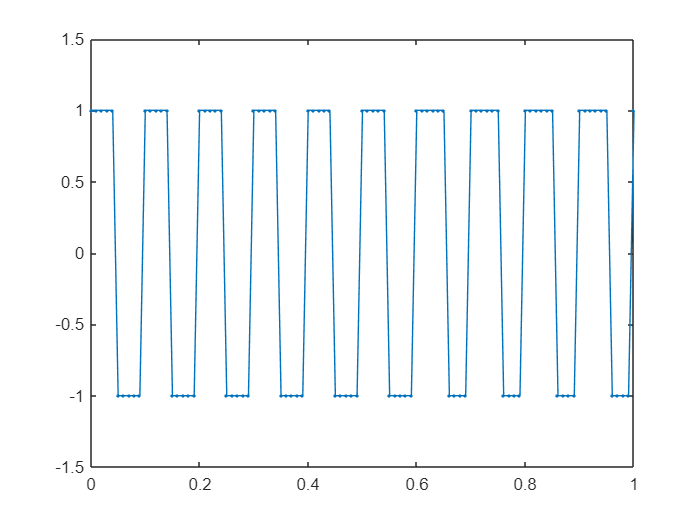

f = 10; %Hz
fs = 100; %Hz
Ts = 1/fs; %s
t = 0:Ts:1;

% Generamos una función cuadrada
% Lo transponemos porque, si no, se crea como un vector fila (lo
% necesitamos columna)
sqr_wave = square(2*pi*f.*t)';

% Multiplicamos la función cuadrada por la ventana de Blackman:
sqr_wave_wind = sqr_wave.*blackman(numel(sqr_wave));

% Ploteamos la señal cuadrada
figure
plot(t, sqr_wave, '.-')
ylim([-1.5 1.5])

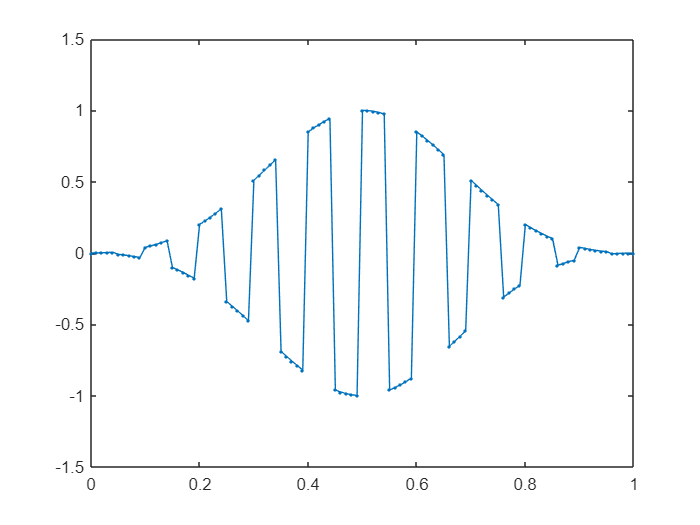

% Ploteamos la señal multliplicada por Blackman
figure
plot(t, sqr_wave_wind, '.-')
ylim([-1.5 1.5])

Upsample:

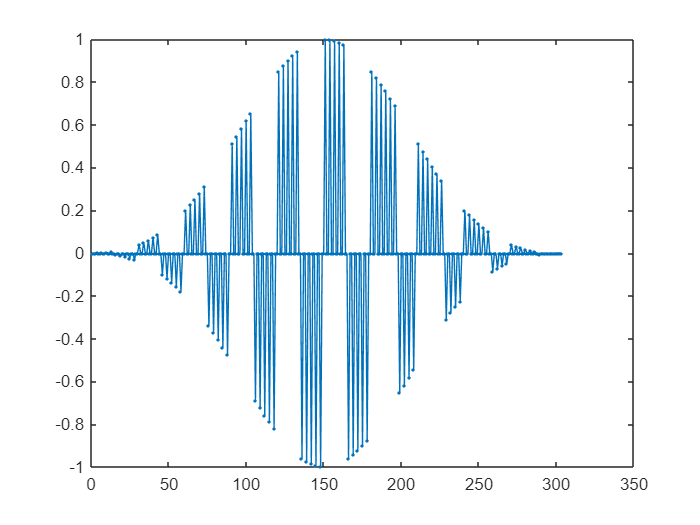

% Se generan N-1 puntos entre muestras, en este caso 3-1 = 2
y_up = upsample(sqr_wave_wind, 3);

%ploteamos el upsample:
figure
plot(y_up, '.-');

Downsampling:

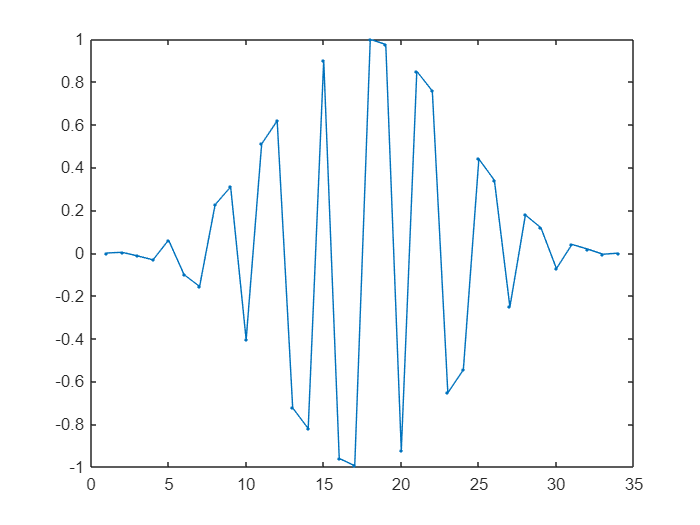

% Con downsample se queda cada N dato y el resto se elimina, en este caso,
% se queda el tercer dato
y_down = downsample(sqr_wave_wind, 3);

%ploteamos el downsample:
figure
plot(y_down, '.-');

Resample:

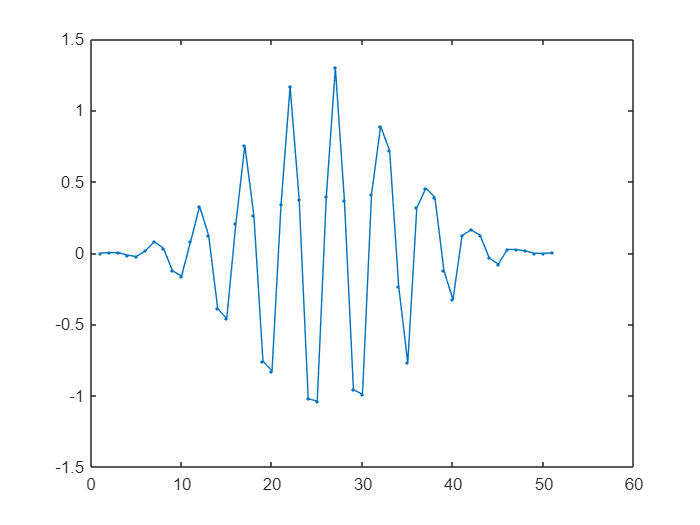

% resample(x,P,Q). Se hace el remuestreo de x a P/Q veces la tasa de muestreo
% original. En este caso: a 1/2 de la tasa original
y_resamp = resample(sqr_wave_wind, 1, 2);

%ploteamos el resample:
figure
plot(y_resamp, '.-');

## Detector de picos

Detectar los picos de la forma de onda cuadrada y del audio del buho

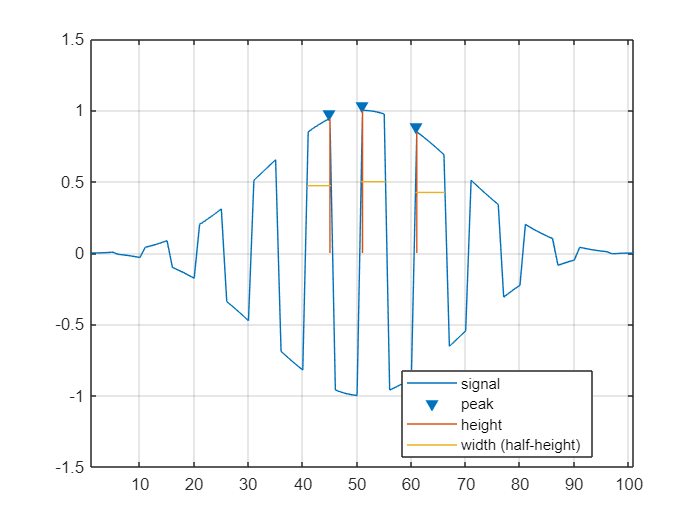

figure

findpeaks(sqr_wave_wind, 'Annotate',"extents", ... %Las anotaciones del plot que se genera
    'WidthReference',"halfheight", ... % Estima el ancho del pinco, en este caso se toma la anchura a una altura igual a la mitad de la altura del pico
    'MinPeakHeight',0.8) % 'MinPeakHeight encuentra sólo los picos que sean mayores a esta altura

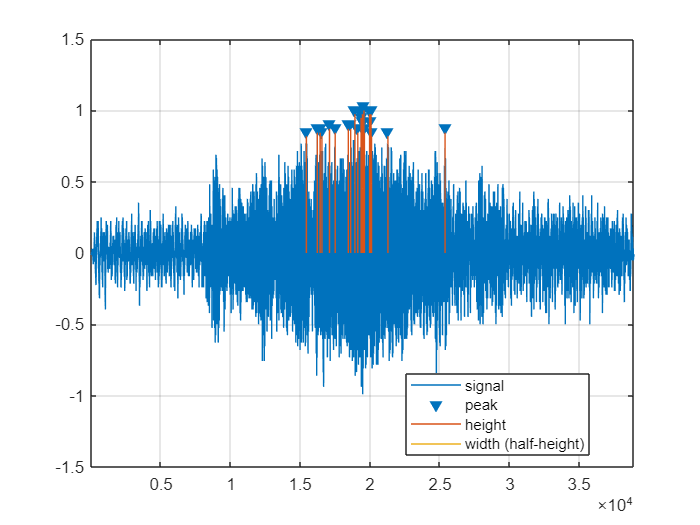

% Findpeaks para el audio del buho:
[y_owl, fs] = audioread("..\..\Utils4SP\Datasets\Owl.wav");

figure
findpeaks(y_owl(:,1), 'Annotate',"extents", ...
    'WidthReference',"halfheight", ...
    'MinPeakHeight',0.8)

% Podemos incluso guardar el tamaño de los picos y su ubicación:
[pks, locs] = findpeaks(y_owl(:,1), 'Annotate',"extents", ...
    'WidthReference',"halfheight", ...
    'MinPeakHeight',0.8)

pks =     0.8180
    0.8439
    0.8439
    0.8180
    0.8697
    0.8439
    0.8697
    0.8697
    0.9730
    0.8439


locs =        15438
       16218
       16423
       16556
       17095
       17500
       18442
       18613
       18918
       19123
